# Run a PPI analysis on a good subject

Get a good subject from the Williams/Flywheel database Pull down the 'Connect Preprocessing for PanLab pipeline data Pull out two sets of time series from two ROIs Implement/run the PPI calculation

CC,BW Scitran Team, 2017

## This is the channel to the flywheel-cni site

fw = scitran('cni');
workDir = fullfile(stRootPath,'local','ppi');
chdir(workDir);

## How our heros downloaded the relevant data from the CNI site

% The files we need are a go-no data files that are CSV
% The BOLD time series nifti

% Here is a good data set.  Why are there three sessions?
[sessions, srch] = fw.search('sessions',...
    'project label','ENGAGE', ...
    'subject code','MV09305');

% Get analyses from the first session with these names
anCPGNG2 = fw.search('analyses in session',...
    'project label','ENGAGE', ...
    'subject code','MV09305', ...
    'session id',sessions{1}.id,...
    'analysis label contains','connectivity-preprocessing (go-no-go 2)');
   
anFLMGNG2 = fw.search('analyses in session',...
    'project label','ENGAGE', ...
    'subject code','MV09305', ...
    'session id',sessions{1}.id,...
    'analysis label contains','first-level-models (go-no-go 2)');

GoFile = fw.search('files in analysis',...
    'analysis id',anFLMGNG2{1}.id,...
    'file name','Go_Onsets.csv');
fw.get(GoFile{1},'destination',fullfile(workDir,'Go.csv'));

NoGoFile = fw.search('files in analysis', ...
    'analysis id',anFLMGNG2{1}.id,...
    'file name','NoGo_Onsets.csv');
fw.get(NoGoFile{1},'destination',fullfile(workDir,'NoGo.csv'));

warpedImage = fw.search('files in analysis',...
    'session id',sessions{1}.id,...
    'analysis id',anCPGNG2{1}.id,...
    'filename','warped_files@@wa01_normalized_func_data.nii.gz');
fw.get(warpedImage{1},'destination',fullfile(workDir,'warpedImage.nii.gz'));

## Starting the analysis

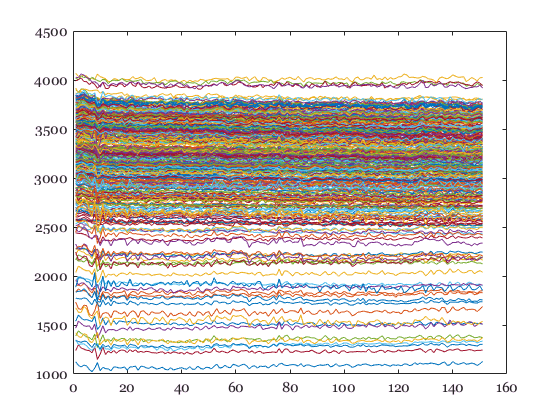


nii = niftiRead(fullfile(pwd,'warpedImage.nii.gz'));
clear roi

nROIs = 2;
roiName = cell(1,nROIs);
roiName{1} = 'Right_10mm_DLPFC_CogCon_FI_44_34_22_cluster.nii';
roiName{2} = 'biLat_10mm_dACC_CogCon_FI_0_18_46_cluster.nii';
roi{1} = niftiRead(fullfile(pwd,'pl_masks',roiName{1}));
roi{2} = niftiRead(fullfile(pwd,'pl_masks',roiName{2}));

clear sz
nTime = size(nii.data,4); 

roiTS = cell(1,nROIs); 
for rr=1:nROIs
    [i,j,k] = ind2sub(size(roi{rr}.data),find(roi{rr}.data == 1));
    nPts = length(i);
    roiTS{rr} = zeros(nTime,nPts);
    for ii=1:nPts
        roiTS{rr}(:,ii) = squeeze(nii.data(i(ii),j(ii),k(ii),:));
    end
end

newGraphWin; plot(roiTS{1}(:,:));

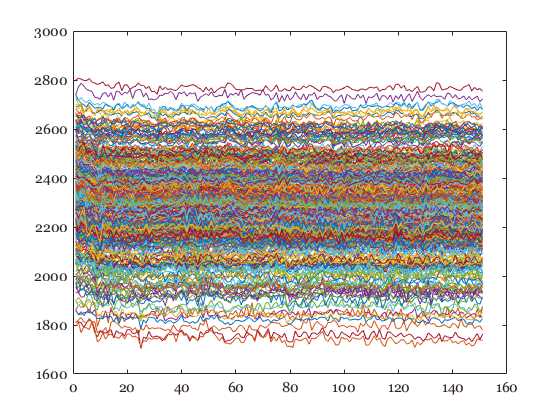

newGraphWin; plot(roiTS{2}(:,:));

## Convert time series to percent modulation

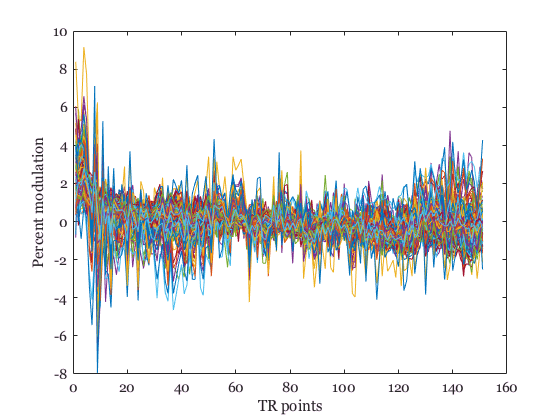

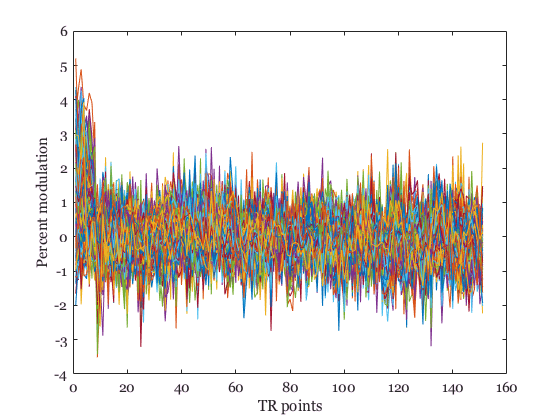

meanTSeries = zeros(nTime,nROIs);
for rr = 1:nROIs
    mn = mean(roiTS{rr},1);
    tSeries2 = bsxfun(@minus, roiTS{rr}, mn);
    tSeries2 = tSeries2*diag(1./mn);
    % Multiply by 100 to get percent
    
    tSeries2 = 100*tSeries2;
    meanTSeries(:,rr) = mean(tSeries2,2);

    newGraphWin; plot(tSeries2); ylabel('Percent modulation'); xlabel('TR points')
end

## Mean time series

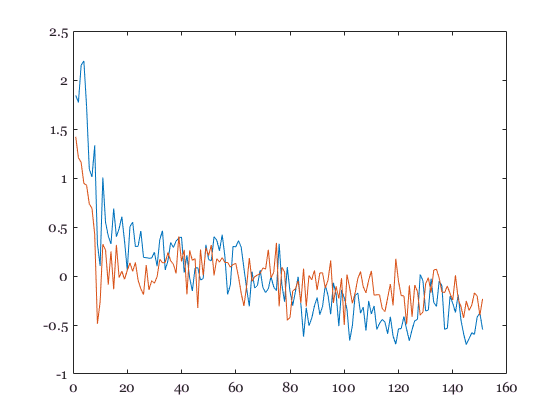


newGraphWin; plot(meanTSeries);

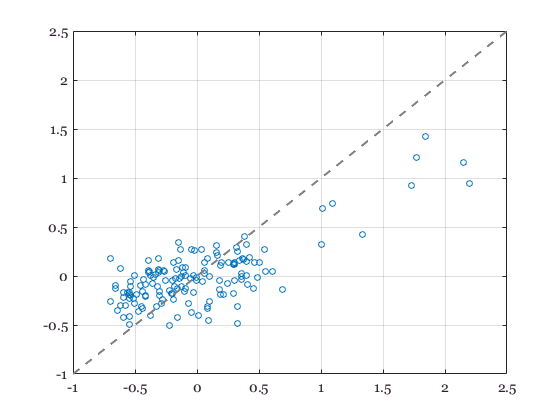

newGraphWin; plot(meanTSeries(:,1),meanTSeries(:,2),'o'); grid on; identityLine(gca);

## Calculate the PPI between these two time series

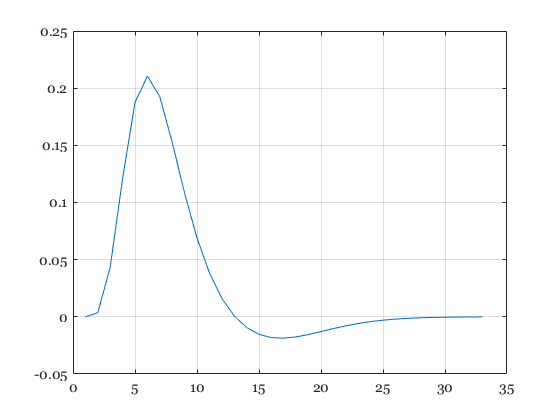

% Fills in the HRF from the parameters
clear xBF;
% The hemodynamic response function types
xBF.name   = 'hrf'; % (with time derivative)';     
xBF.dt     = 1;         % The TR of the acquisition
xBF.order  = 1;
xBF = spm_get_bf(xBF);

newGraphWin; plot(xBF.bf); grid on

## Psychological vector

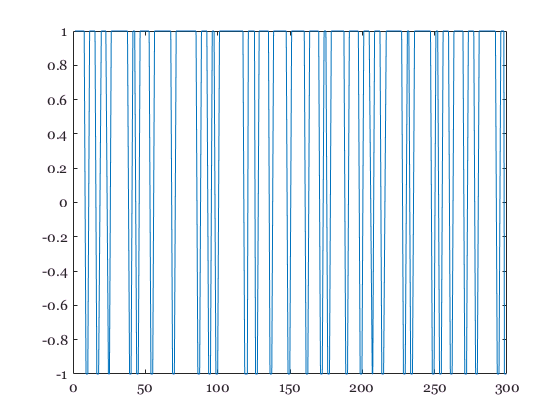



TR = 2; % TR of the acquisition
% onset files are lists of stimulus onsets from beginning of nifti
goOnsets = csvread(fullfile(workDir, 'Go.csv'), 1, 3);
noGoOnsets = csvread(fullfile(workDir, 'NoGo.csv'), 1, 3);
[tvals,idx] = sort([goOnsets; noGoOnsets]);
val = [ones(size(goOnsets)); -1*ones(size(noGoOnsets))];
val = val(idx);
plot(tvals,val,'-')

## Interpolate to the TR sample spacing

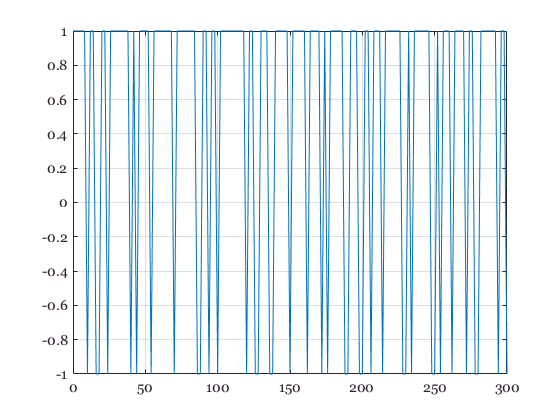

TRTimes = 0:TR:(TR*(nTime-1));
psych = interp1(tvals,val,TRTimes,'linear','extrap');
psych(psych < 0) = -1; psych(psych > 0) = 1;
newGraphWin; plot(TRTimes,psych); grid on;

## This showed us that the spm_Volterra and a simple convolution were the same


% goReg=zeros(nTime, 1);
% % HACK round() is likely not ideal
% % This adds a regressor for the timepoint closest to the "Go" stimulus onset.
% goReg(round(goOnsets/TR)) = 1;
% 
% noGoReg=zeros(nTime, 1);
% noGoReg(round(noGoOnsets/TR)) = -1;
% 
% % We wrap the regressor in SPM's data format and convolve it with the
% % HRF generated above.
% clear U;
% U.u=goReg;
% U.name={'go'};
% goConvreg=spm_Volterra(U, xBF.bf);
% 
% clear U;
% U.u=noGoReg;
% U.name={'nogo'};
% noGoConvreg=spm_Volterra(U, xBF.bf);
% 
% newGraphWin;plot([goReg noGoReg goConvreg noGoConvreg]);

## Convolution form

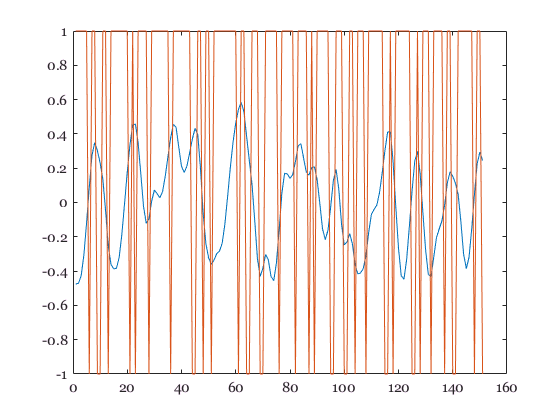


psychConv = conv2(xBF.bf(:),psych(:));
psychConv = psychConv(1:nTime);
psychConv = psychConv - mean(psychConv(:));
newGraphWin; plot(psychConv); hold on; plot(psych);

## Create the matrix for the regression Beta values for predicting from roi1 to roi2


reg = [meanTSeries(:,1) , psychConv,  psychConv .* meanTSeries(:,1) ];
beta = reg\meanTSeries(:,2);

beta(3)/sum(beta)

ans = 7.3066

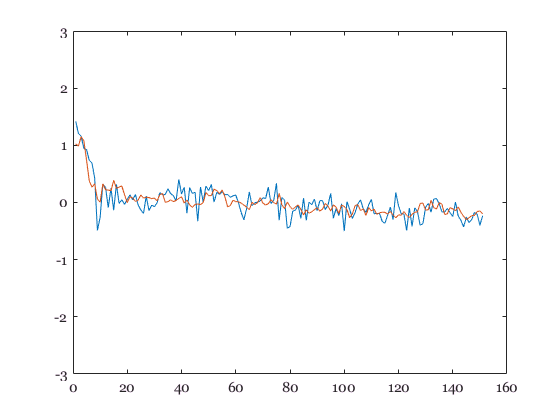

newGraphWin;
prediction = reg*beta;
plot([meanTSeries(:,2), prediction])
set(gca,'ylim',[-3 3]);


% If you want to see the regression terms, plot tis

% plot(reg);
% legend({'TS','Psych','Product'});
% grid on


## Beta values from roi2 to roi1


reg = [meanTSeries(:,2) , psychConv,  psychConv .* meanTSeries(:,2) ];
beta = reg\meanTSeries(:,1);
beta

beta =     1.2056
    0.1876
   -0.7889


beta(3)/sum(abs(beta))

ans = -0.3615

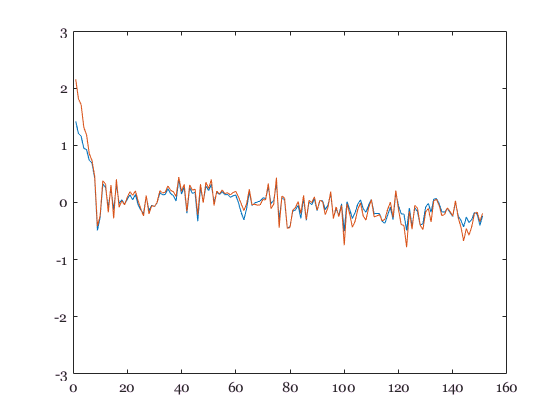


newGraphWin;
prediction = reg*beta;
plot([meanTSeries(:,2), prediction])
set(gca,'ylim',[-3 3]);